clc
clear all
close all 

% System definition

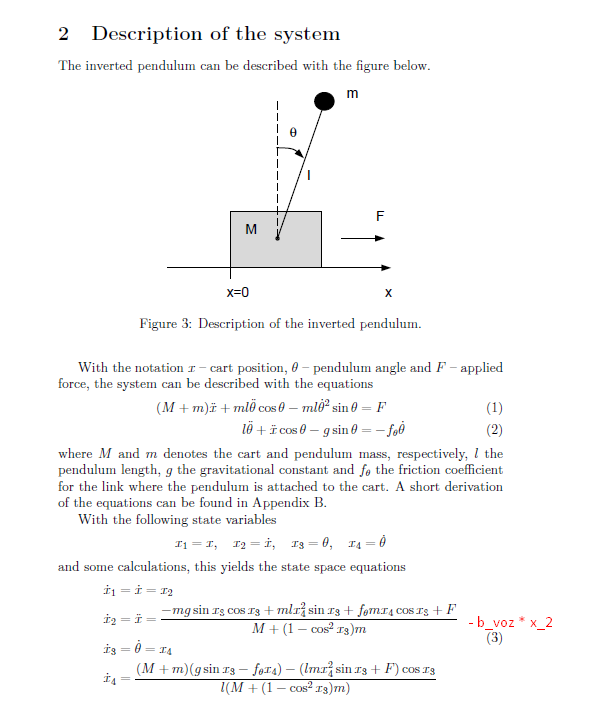

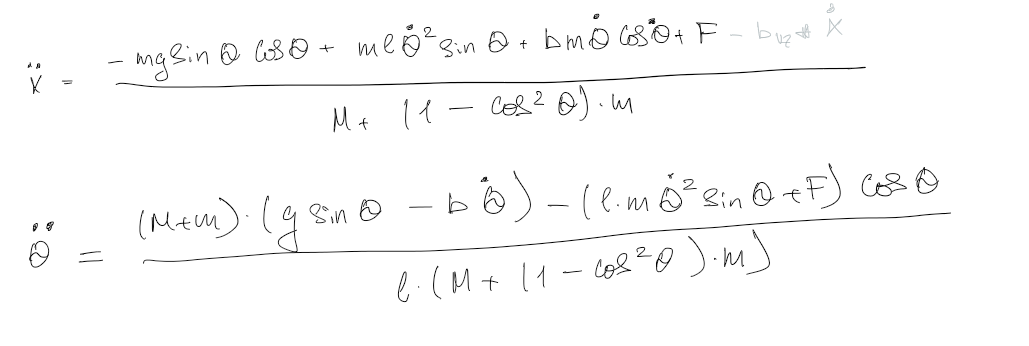

    M = 0.5     % mass of the cart

M = 0.5000

    m = 0.2     % mass of the pendulum

m = 0.2000

    b = 0.1     % coefficient of the friction rotation

b = 0.1000

    b_c = 0.5   % coefficient of the friction translation

b_c = 0.5000

    I = 0.006   % mass moment of inertia of the pendulum

I = 0.0060

    g = 9.81    % acceleration of gravity

g = 9.8100

    l = 0.3     % length to pendulum center of mass    

l = 0.3000

#### Rovnice a linearizace:


$$$
x = 
\pmatrix{
       x \cr
       \dot{x} \cr
       \theta \cr
       \dot{\theta}
} 
= 
\pmatrix{
       x_1 \cr
       x_2 \cr
       x_3 \cr
       x_4
} 
\\

\ddot{x} = \frac{-m.g.sin(\theta).cos(\theta) + m.l.\dot{\theta}^2.sin(\theta) + b.m.\dot{\theta}.cos(\theta) + F -b_{vz}.\dot{x}}{M+(1-cos^2(\theta)).m}\\
\ddot{\theta} = \frac{(M+m)(g.sin(\theta)-b.\dot{\theta})-(l.m.\dot{\theta}^2.sin(\theta)+F).cos(\theta)}{l.(M+(1-cos^2(\theta)).m)}\\

\dot{x}_1 = x_2\\
\dot{x}_2 = \frac{-m.g.sin(x_3).cos(x_3) + m.l.x_{4}^2.sin(x_3) + b.m.x_{4}.cos(x_3) + F -b_{vz}.x_2}{M+(1-cos^2(x_3)).m}\\
\dot{x}_3 = x_4\\
\dot{x}_4 = \frac{(M+m)(g.sin(x_3)-b.x_4)-(l.m.x_{4}^2.sin(x_3)+F).cos(x_3)}{l.(M+(1-cos^2(x_3)).m)}
$$$


syms x1 x2 x3 x4 dx1 dx2 dx3 dx4 F

state_vec = [x1; x2; x3; x4]

$$state\_vec = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ x_{4} \end{array}\right)$$

% (*) Inverted pendulum reasonable:

eq1 = x2 == dx1;
eq2 = (-m*g*sin(x3)*cos(x3) + m*l*(x4^2)*sin(x3) + b*m*x4*cos(x3) - b_c*x2 + F)/(M+(1-(cos(x3))^2)*m) == dx2;
eq3 = x4 == dx3;
eq4 = ((M+m)*(g*sin(x3)-b*x4)-(l*m*x4^2*sin(x3)+F)*cos(x3))/(l*(M+(1-(cos(x3))^2)*m)) == dx4 ;
eqs = [eq1; eq2; eq3; eq4];

% bod linearizace:
point_of_lin = [0; 0; 0; 0];

% ---------------------------------------------------------

% % (*) Inverted pendulum Control Tutorials:
% 
% q = (I+m*l^2)*(M+m) - (m*l)^2;
% 
% eq1 = x2 == dx1;
% eq2 = ((-b*(I+m*l^2))/(q))*x2 + ((g*(m*l)^2)/(q))*x3 + (((M+m)*(I+m*l^2))/(q))*F == dx2;
% eq3 = x4 == dx3;
% eq4 = ((-b*m*l)/(q))*x2 + ((m*l*(M+m))/(q))*F + ((m*g*l*(I+m*l^2))/(q))*x4 == dx4;
% 
% eqs = [eq1; eq2; eq3; eq4];
% 
% % bod linearizace:
% point_of_lin = [0; 0; 0; 0];

% ---------------------------------------------------------

eqs_lin = subs(eqs, x3, point_of_lin(3))

$$eqs\_lin = \left(\begin{array}{c} x_{2}={\mathrm{dx}}_{1}\\ 2\,F-x_{2}+\frac{x_{4}}{25}={\mathrm{dx}}_{2}\\ x_{4}={\mathrm{dx}}_{3}\\ -\frac{20\,F}{3}-\frac{7\,x_{4}}{15}={\mathrm{dx}}_{4} \end{array}\right)$$

A = double(jacobian(lhs(eqs_lin), state_vec))

A =          0    1.0000         0         0
         0   -1.0000         0    0.0400
         0         0         0    1.0000
         0         0         0   -0.4667


% p = I*(M+m)+M*m*l^2; %denominator for the A and B matrices

% A = [0      1              0           0;
%      0 -(I+m*l^2)*b/p  (m^2*g*l^2)/p   0;
%      0      0              0           1;
%      0 -(m*l*b)/p       m*g*l*(M+m)/p  0];

B = double(jacobian(lhs(eqs_lin), F))

B =          0
    2.0000
         0
   -6.6667



% B = [     0;
%      (I+m*l^2)/p;
%           0;
%         m*l/p];

C = [[1 0 0 0];[0 0 1 0]]

C =      1     0     0     0
     0     0     1     0


D = [0; 0]

D =      0
     0


inv_pend_linsys = ss(A, B, C, D)

inv_pend_linsys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0       -1        0     0.04
   x3        0        0        0        1
   x4        0        0        0  -0.4667
 
  B = 
           u1
   x1       0
   x2       2
   x3       0
   x4  -6.667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



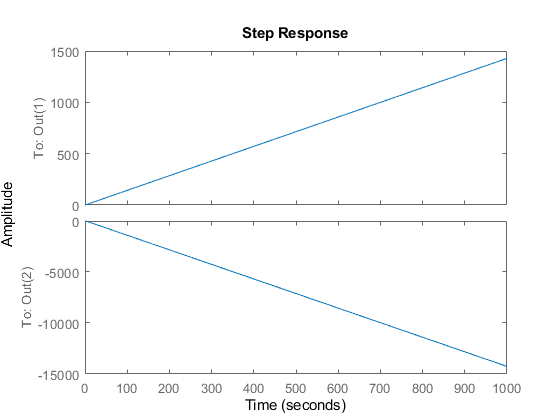

step(inv_pend_linsys)

[p, z] = pzmap(inv_pend_linsys)

p =          0
   -1.0000
         0
   -0.4667



z =

  0×1 empty double column vector



% controllability: 

rank(ctrb(inv_pend_linsys))

ans = 3

% obserervability

rank(obsv(inv_pend_linsys))

ans = 4

#### LQR controller: 

Q = [[1 0 0 0]; [0 0 0 0]; [0 0 10 0]; [0 0 0 0]];                    % state cost matrix
R = [[0.05]];                                                            % input cost matrix
% N = [[1]];                                                               % state input weight matrix

[K, S, e] = lqr(inv_pend_linsys, Q, R)

K =     0.1413   -0.1027  -14.1351   -2.0258


S = 	1.0e+08 *

    3.1531    3.1531    0.3153    0.9459
    3.1531    3.1531    0.3153    0.9459
    0.3153    0.3153    0.0315    0.0946
    0.9459    0.9459    0.0946    0.2838


e =   -0.0000 + 0.0000i
  -0.9960 + 0.0000i
  -6.8854 + 6.8772i
  -6.8854 - 6.8772i


inv_pend_sys_lqr = ss(A-B*K, B, C, D)

inv_pend_sys_lqr =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2  -0.2827  -0.7946    28.27    4.092
   x3        0        0        0        1
   x4   0.9423  -0.6848   -94.23   -13.97
 
  B = 
           u1
   x1       0
   x2       2
   x3       0
   x4  -6.667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



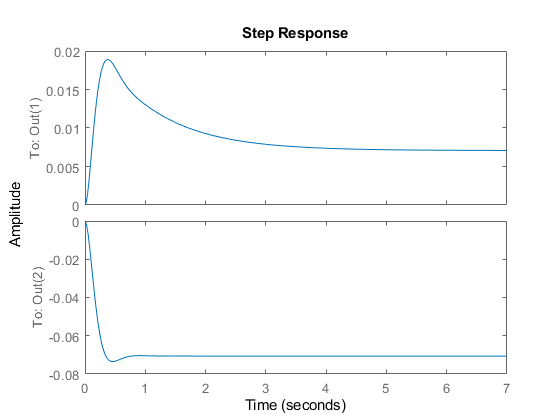

% rescaling:

k = dcgain(inv_pend_sys_lqr);
kr = [1/k(1) 1 1/k(2) 1];
inv_pend_sys_lqr.B = inv_pend_sys_lqr.B.*kr'; 
step(inv_pend_sys_lqr)

% Simulating:
t = 0:0.01:5;
u =0.2*ones(size(t));
[y,t,x]=lsim(inv_pend_sys_lqr,u,t);
tiledlayout(2,1);

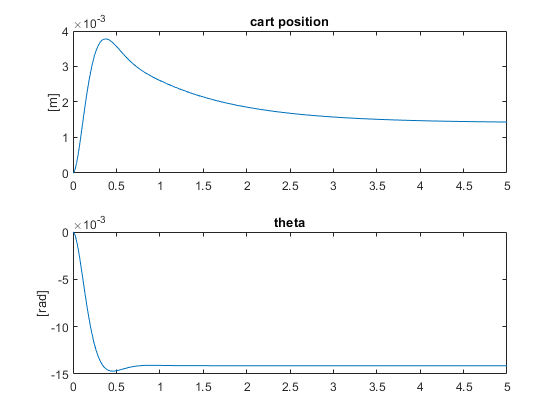


% Top plot
ax1 = nexttile;
plot(ax1,t,y(:, 1));
title(ax1,'cart position');
ylabel(ax1,'[m]');

% Bottom plot
ax2 = nexttile;
plot(ax2,t,y(:, 2));
title(ax2,'theta');
ylabel(ax2,'[rad]');